clc; clear all; close all;


## 1

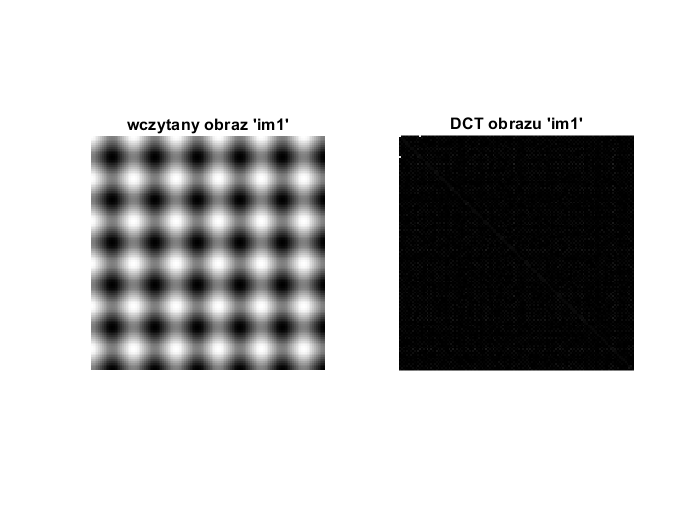


[x,cmap] = imread("im1.png");   %wczytanie obrazu
X1 = dct2(x);

%imshow(X1);
k = max(max(X1));
s = 0.001*k;    %znaczące >= 0.001*max
znaczace_i =[];
znaczace_j = [];
for i = 1:length(X1)
    for j = 1:length(X1)
        if(X1(i,j)>=s)
            znaczace_i = [znaczace_i,i];
            znaczace_j = [znaczace_j,j];
        end
    end
end

wycieteX1 = X1;
for n = 2:2:length(znaczace_j)
    wycieteX1(znaczace_i(n),znaczace_j(n)) = 0;
end
%{
tran = wycieteX1.';
newX1 = dct2(tran);
figure;
imshow(newX1,cmap);
figure;
imshow(newX,cmap);
err = max(max(abs(newX-newX1)));
disp(err);
%}

newX = idct2(wycieteX1);    %transformata odwrotna

figure; 
subplot(121);
imshow(x,cmap);
title("wczytany obraz 'im1'");
subplot(122);
imshow(skaladB(X1),cmap);
title("DCT obrazu 'im1'")

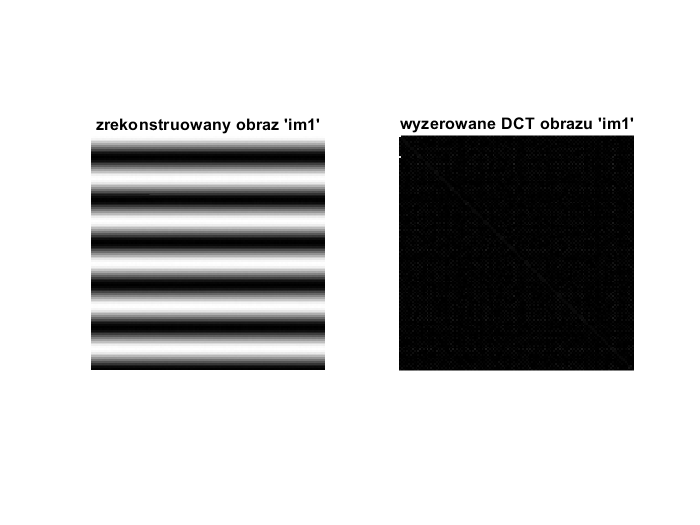


figure;
subplot(121);
imshow(newX,cmap);
title("zrekonstruowany obraz 'im1'")
subplot(122);
imshow(skaladB(wycieteX1),cmap);
title("wyzerowane DCT obrazu 'im1'")

## 2

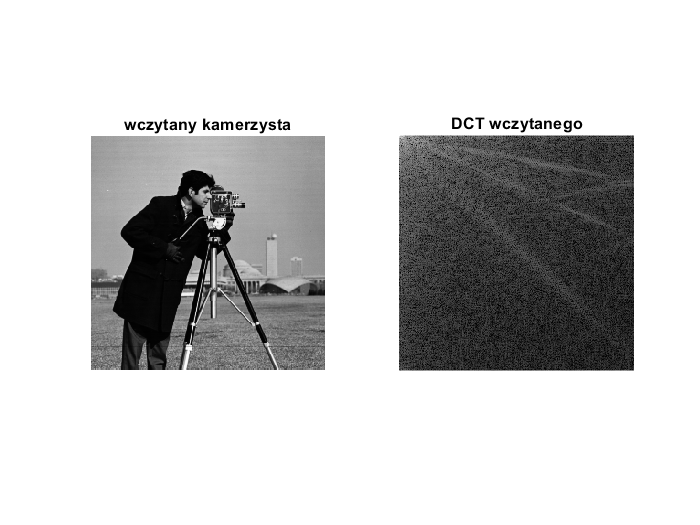


clear;
[x,cmap] = imread("cameraman.tif");   %wczytanie obrazu
[M,N]=size(x);
x = double(x);

%a  
  X1 = dct2(x);
  figure;
  subplot(121)
  imshow(x,cmap);
  title("wczytany kamerzysta")  
  subplot(122)
  imshow(skaladB( X1 ), cmap);
  title("DCT wczytanego")

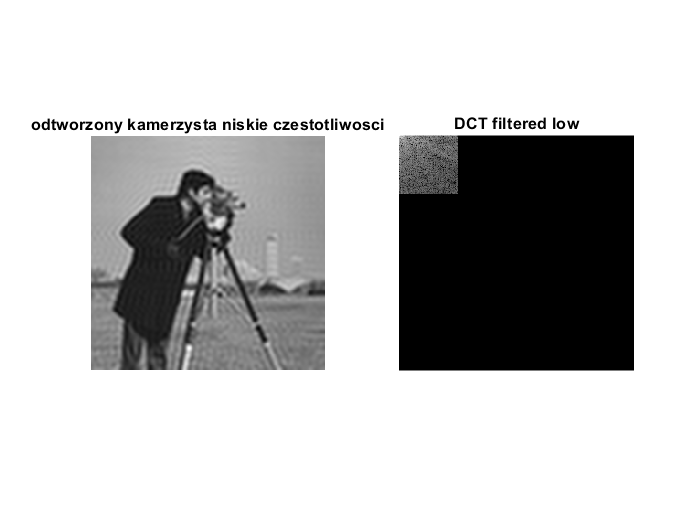

    
  %niskie => lewy górny; wysokie => reszta
  K=64;
  HH=ones(M,N); HL=zeros(M,N);
  HH(1:K,1:K) = zeros(K,K); HL(1:K,1:K) = ones(K,K);
  %h = fftshift2D(real(ifft2(fftshift2D(HH))));
  %imshow(255*HH,cmap);
  %mesh(h);
  
  X1filteredLow = X1 .* HL;
  X1filteredHigh = X1 .* HH;
  xRecLow = idct2(X1filteredLow);
  xRecHigh = idct2(X1filteredHigh);
  
  figure;
  subplot(121);
  imshow(xRecLow,cmap);
  title("odtworzony kamerzysta niskie czestotliwosci")
  subplot(122);
  imshow(skaladB(X1filteredLow),cmap);
  title("DCT filtered low")

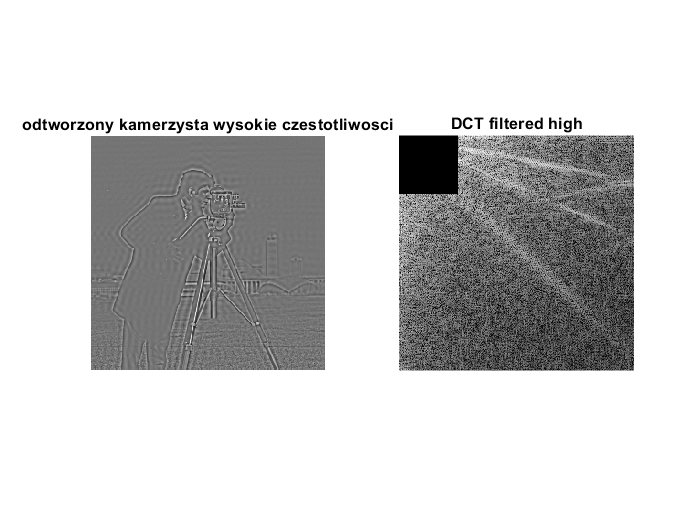

  
  figure;
  subplot(121);
  imshow(xRecHigh,cmap);
  title("odtworzony kamerzysta wysokie czestotliwosci")
  subplot(122);
  imshow(skaladB(X1filteredHigh),cmap);
  title("DCT filtered high")

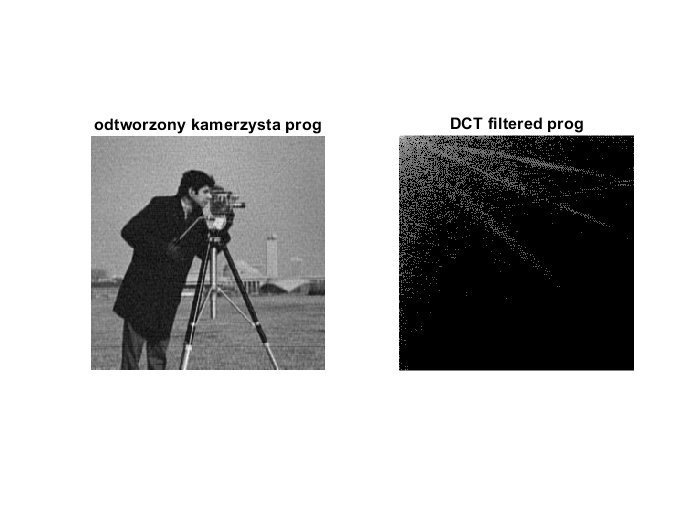

  
%b
  s = 0.001*max(max(X1));
  znaczace_i =[];
  znaczace_j = [];
  wycieteX1 = X1;
  for i = 1:length(X1)
    for j = 1:length(X1)
      if(abs(X1(i,j))<=s)
        wycieteX1(i,j) = 0;
      end
    end
  end
  
  xRecWycinam = idct2(wycieteX1);
  figure;
  subplot(121);
  imshow(xRecWycinam,cmap);
  title("odtworzony kamerzysta prog")
  subplot(122);
  imshow(skaladB(wycieteX1),cmap);
  title("DCT filtered prog")

## 3

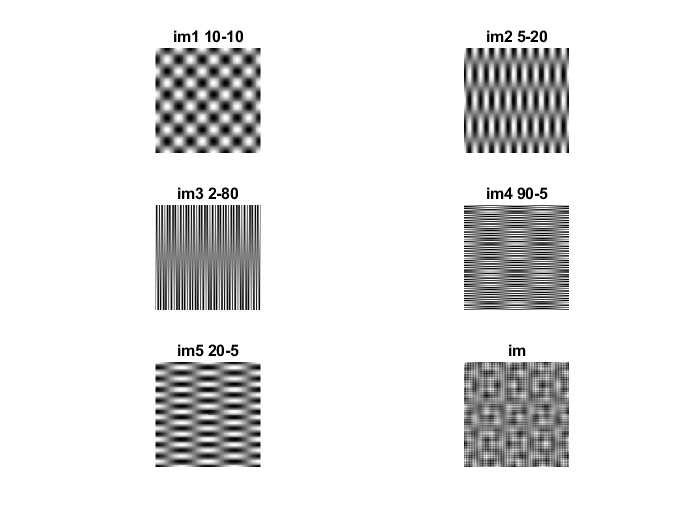

im1 = zeros(128,128);
im1(10,10) = 1;
im1 = idct2(im1);

im2 = zeros(128,128);
im2(5,20) = 1;
im2 = idct2(im2);

im3 = zeros(128,128);
im3(2,80) = 1;
im3 = idct2(im3);

im4 = zeros(128,128);
im4(90,5) = 1;
im4 = idct2(im4);

im5 = zeros(128,128);
im5(20,5) = 1;
im5 = idct2(im5);

im = im1+im2+im3+im4+im5;

figure;
subplot(321)
imshow(im1,cmap);
title('im1 10-10');
subplot(322)
imshow(im2,cmap);
title('im2 5-20');
subplot(323)
imshow(im3,cmap);
title('im3 2-80');
subplot(324)
imshow(im4,cmap);
title('im4 90-5');
subplot(325)
imshow(im5,cmap);
title('im5 20-5');
subplot(326)
imshow(im,cmap);
title('im');

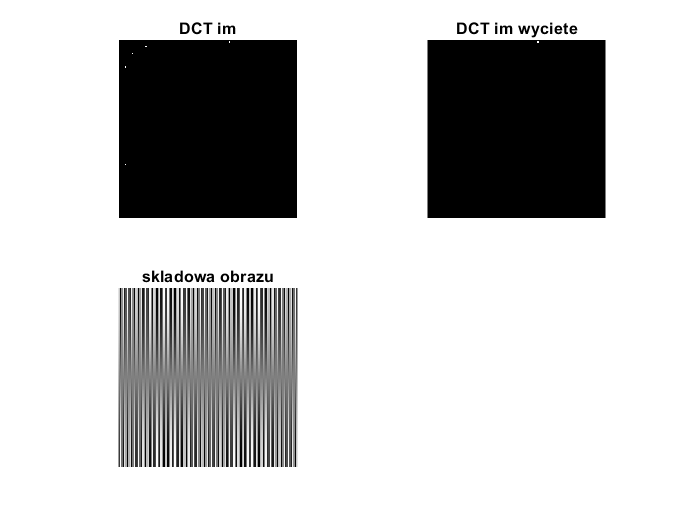



DCT = dct2(im);

znaczace_m =[];
znaczace_n = [];
for m=1:length(DCT)
    for n = 1:length(DCT)
        if abs(DCT(m,n))>= 0.99
            znaczace_m = [znaczace_m,m];
            znaczace_n = [znaczace_n,n];
        end
    end
end

noweDCT = DCT;
for n = 2:length(znaczace_m)
    noweDCT(znaczace_m(n),znaczace_n(n)) = 0;
end



figure;
subplot(221)
imshow(DCT,cmap);
title("DCT im")
subplot(222)
imshow(noweDCT,cmap);
title("DCT im wyciete")
subplot(223)
imshow(idct2(noweDCT),cmap);
title("skladowa obrazu");

## 4

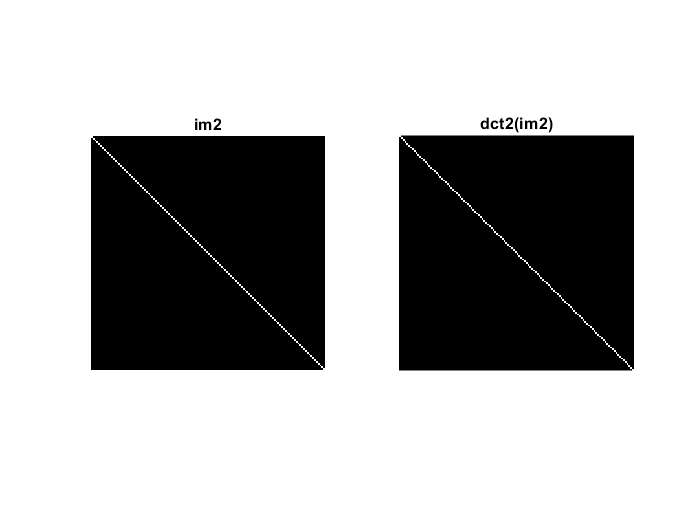

clear;
[x,cmap] = imread("im2.png");
%x = double(x);
figure;
subplot(121);
imshow(x,cmap);
title("im2");
subplot(122);
imshow(dct2(x),cmap);
title('dct2(im2)')